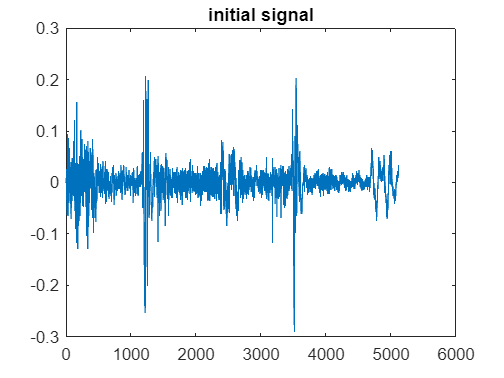

clear
clc
close all

load('X_in_0.txt')

plot(X_in_0)
title('initial signal')

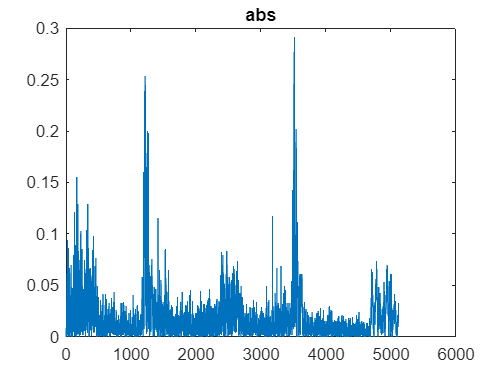

plot(abs(X_in_0))
title('abs')

loga = log(abs(X_in_0)+1)

loga =          0
    0.0010
    0.0092
    0.0044
    0.0327
    0.0085
    0.0174
    0.0081
    0.0128
    0.0252


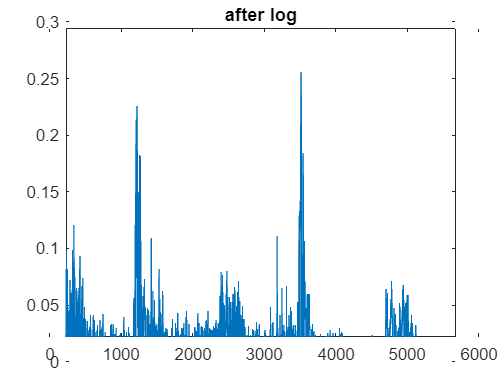


plot(loga)
title('after log')

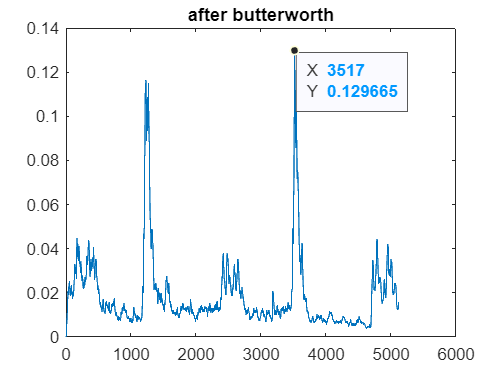

[b,a] = butter(1, 8/500);
%freqz(b, a, 1024, 1000);

log_filtered = filter(b, a, loga);
plot(log_filtered)
title('after butterworth')

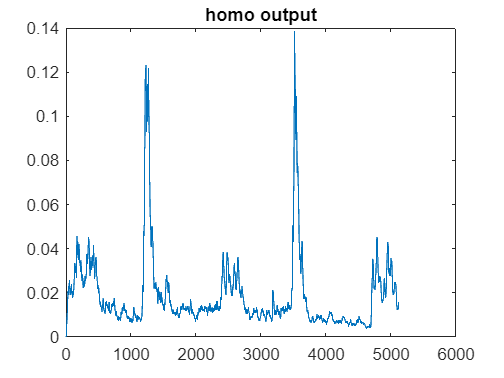

plot(exp(log_filtered)-1)
title('homo output')

firedecim = dsp.FIRDecimator(20)

firedecim =   dsp.FIRDecimator with properties:

   Main
    DecimationFactor: 20
     NumeratorSource: 'Property'
           Numerator: [0 -6.3125e-07 -1.4075e-06 -2.3192e-06 -3.3488e-06 -4.4710e-06 -5.6525e-06 -6.8522e-06 -8.0222e-06 -9.1088e-06 -1.0054e-05 -1.0797e-05 -1.1276e-05 -1.1432e-05 -1.1209e-05 -1.0559e-05 -9.4422e-06 -7.8323e-06 … ] (1×480 double)
           Structure: 'Direct form'

  Show all properties


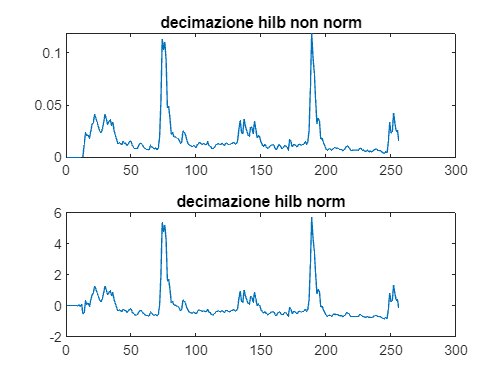


figure(2)
subplot(2,1,1)
x_out = firedecim(exp(log_filtered)-1);
plot(x_out)
title('decimazione hilb non norm')

subplot(2,1,2)
x_out_n = firedecim(normalize(exp(log_filtered)-1));
plot(x_out_n)
title('decimazione hilb norm')

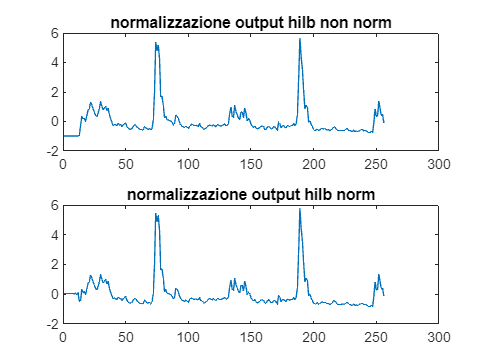

figure(3)
subplot(2,1,1)
x_out_norm1 = normalize(x_out);
plot(x_out_norm1)
title('normalizzazione output hilb non norm')

subplot(2,1,2)
x_out_norm2 = normalize(x_out_n);
plot(x_out_norm2)
title('normalizzazione output hilb norm')